clc
clearvars
close all

nlist = readtable("./data/nlist.csv");
nlist.Properties.VariableNames = {'Name','Label','Group'};
nlist.Name = string(nlist.Name);
elist_dy = readtable("./data/elist_dynamic.csv");

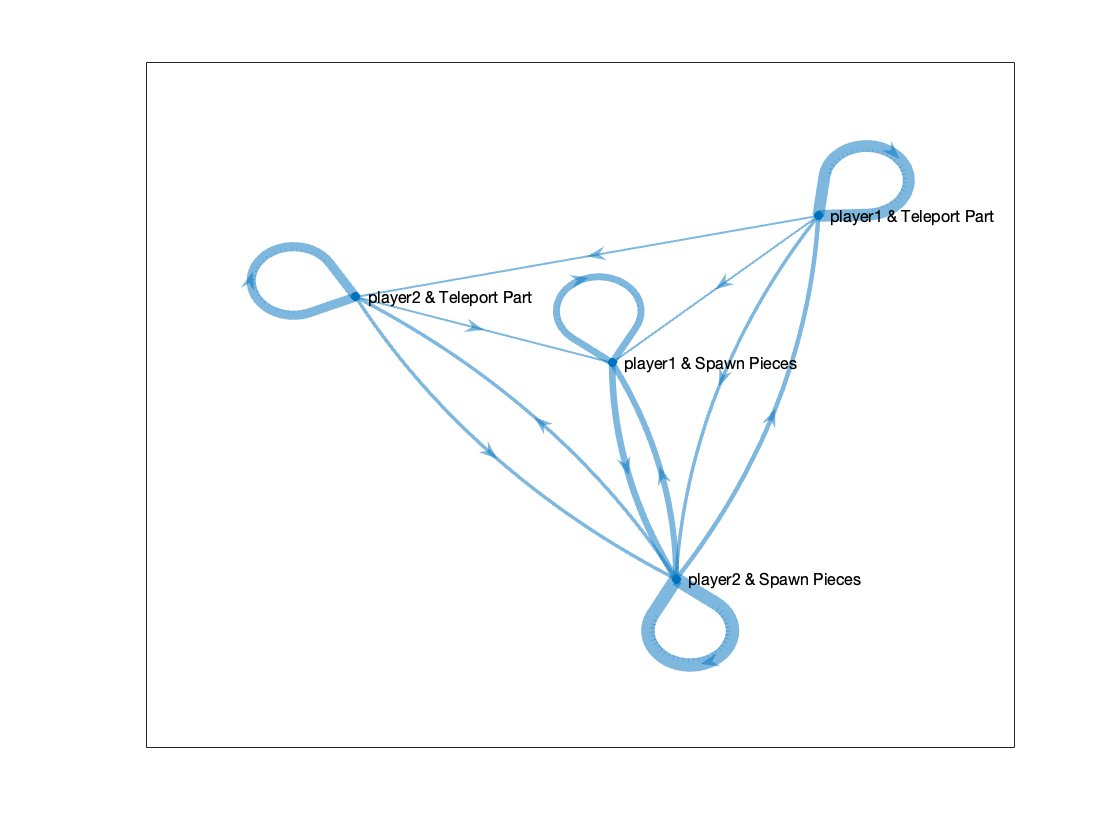

num_edges = size(elist_dy,1);
snodes = elist_dy.Source;
tnodes = elist_dy.Target;

s = snodes(1);
t = tnodes(1);
elist = [s,t];
w = 1;
etable = table(elist,w, 'VariableNames',{'EndNodes','Weight'});
G = digraph(etable);

for i=2:num_edges
    s = snodes(i);
    t = tnodes(i);
    [edge_exist,idx] = ismember([s,t],G.Edges.EndNodes,'rows');

    if(all(edge_exist))
        G.Edges.Weight(idx) = G.Edges.Weight(idx)+1;
    else
        G = addedge(G,s,t,1);
    end
    plot(G,'NodeLabel',nlist.Label,'LineWidth',sqrt(G.Edges.Weight))
    drawnow
end